# Sample

clear, close all, clc
A = imread('cameraman.tif');
A = im2double(A);
%A = imresize(A,[ 64]);
N = 8; %size of the block

sampling_rate = 48;
out = blockproc(A,[N N],@(block_struct) comp_sen(block_struct.data,sampling_rate));

figure('name','Compressive sensing image reconstructions')
subplot(1,2,1), imshow(A), title('original'), axis image
subplot(1,2,2), imshow(out), 
title(['reconstruction with ',num2str((sampling_rate/(N*N))*100), '% sampling rate']), axis image
colormap gray

# Different sampling rate for grayscale image

%A = imresize(A,[ 64]);
N = 8; %size of the block

%subplot(4,4,1), imshow(A), title('original'), axis image

for sampling_rate = 4:4:64
    A = imread('cameraman.tif');
    A = im2double(A);
    out = blockproc(A,[N N],@(block_struct) comp_sen(block_struct.data,sampling_rate));
    psnr_ =psnr(out,A);
    ssim_ = ssim(out,A);
    subplot(4,4,sampling_rate/4); imshow(out);
    title({ [num2str((sampling_rate/(N*N))*100), '%'] ...
        ['psnr = ', num2str(psnr_)] ...
        ['ssim = ', num2str(ssim_)]}); axis image
    colormap gray
end
set(gcf, 'Position', [0 0 800 800])
f=gcf;
exportgraphics(f,'sampling_rates.pdf')

# Different sampling rate for colored image

N = 8; %size of the block
for sampling_rate = 4:4:64
    A = imread('pride.png');
    A = imresize(A,[256 256]);
    A = im2double(A);

    ycbcrImage = rgb2ycbcr(A);
    Y = ycbcrImage(:,:,1); 
    Cb = ycbcrImage(:,:,2); 
    Cr = ycbcrImage(:,:,3);

    out_Y = blockproc(Y,[N N],@(block_struct) comp_sen(block_struct.data,sampling_rate));
    out_Cb = blockproc(Cb,[N N],@(block_struct) comp_sen(block_struct.data,sampling_rate));
    out_Cr = blockproc(Cr,[N N],@(block_struct) comp_sen(block_struct.data,sampling_rate));
    out = cat(3, out_Y, out_Cb, out_Cr);
    out = ycbcr2rgb(out);
    psnr_ =psnr(out,A);
    ssim_ = ssim(out,A);
    subplot(4,4,sampling_rate/4); imshow(out);
    title({ [num2str((sampling_rate/(N*N))*100), '%'] ...
        ['psnr = ', num2str(psnr_)] ...
        ['ssim = ', num2str(ssim_)]}); axis image
    colormap gray
end
set(gcf, 'Position', [0 0 800 800])
f=gcf;
exportgraphics(f,'sampling_rates_rgb.pdf')

Matrix ill-conditioned.  Returning previous iterate.  (See Section 4 of notes for more information.)
Matrix ill-conditioned.  Returning previous iterate.  (See Section 4 of notes for more information.)
Matrix ill-conditioned.  Returning previous iterate.  (See Section 4 of notes for more information.)
Matrix ill-conditioned.  Returning previous iterate.  (See Section 4 of notes for more information.)
Matrix ill-conditioned.  Returning previous iterate.  (See Section 4 of notes for more information.)
Matrix ill-conditioned.  Returning previous iterate.  (See Section 4 of notes for more information.)
Matrix ill-conditioned.  Returning previous iterate.  (See Section 4 of notes for more information.)
Matrix ill-conditioned.  Returning previous iterate.  (See Section 4 of notes for more information.)
Matrix ill-conditioned.  Returning previous iterate.  (See Section 4 of notes for more information.)
Matrix ill-conditioned.  Returning previous iterate.  (See Section 4 of notes for more info

Matrix ill-conditioned.  Returning previous iterate.  (See Section 4 of notes for more information.)
Matrix ill-conditioned.  Returning previous iterate.  (See Section 4 of notes for more information.)
Matrix ill-conditioned.  Returning previous iterate.  (See Section 4 of notes for more information.)
Matrix ill-conditioned.  Returning previous iterate.  (See Section 4 of notes for more information.)
Matrix ill-conditioned.  Returning previous iterate.  (See Section 4 of notes for more information.)
Matrix ill-conditioned.  Returning previous iterate.  (See Section 4 of notes for more information.)
Matrix ill-conditioned.  Returning previous iterate.  (See Section 4 of notes for more information.)
Matrix ill-conditioned.  Returning previous iterate.  (See Section 4 of notes for more information.)
Matrix ill-conditioned.  Returning previous iterate.  (See Section 4 of notes for more information.)
Matrix ill-conditioned.  Returning previous iterate.  (See Section 4 of notes for more info

Matrix ill-conditioned.  Returning previous iterate.  (See Section 4 of notes for more information.)
Matrix ill-conditioned.  Returning previous iterate.  (See Section 4 of notes for more information.)
Matrix ill-conditioned.  Returning previous iterate.  (See Section 4 of notes for more information.)
Matrix ill-conditioned.  Returning previous iterate.  (See Section 4 of notes for more information.)
Matrix ill-conditioned.  Returning previous iterate.  (See Section 4 of notes for more information.)
Matrix ill-conditioned.  Returning previous iterate.  (See Section 4 of notes for more information.)
Matrix ill-conditioned.  Returning previous iterate.  (See Section 4 of notes for more information.)
Matrix ill-conditioned.  Returning previous iterate.  (See Section 4 of notes for more information.)
Matrix ill-conditioned.  Returning previous iterate.  (See Section 4 of notes for more information.)
Matrix ill-conditioned.  Returning previous iterate.  (See Section 4 of notes for more info

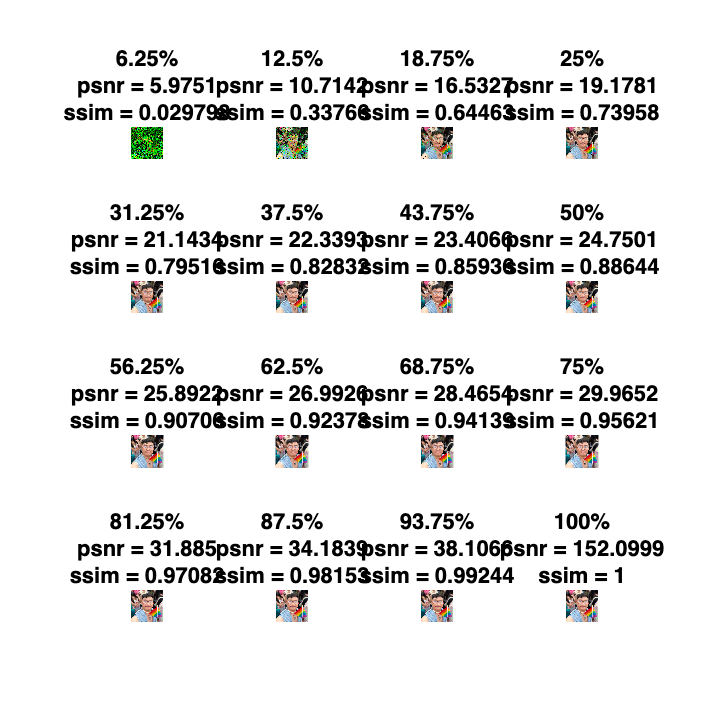

function x1 = comp_sen(in,sampling)
    x = in;
    x = double(x(:));

    n = length(x);
    %___MEASUREMENT MATRIX___
    m = sampling; % NOTE: small error still present after increasing m to 1500;
    Phi = randn(m,n);
        %__ALTERNATIVES TO THE ABOVE MEASUREMENT MATRIX___ 
        %Phi = (sign(randn(m,n))+ones(m,n))/2; % micro mirror array (mma) e.g. single
        %pixel camera Phi = orth(Phi')'; % NOTE: See Candes & Romberg, l1
        %magic, Caltech, 2005.
    %___COMPRESSION___
    y = Phi*x;
    %___THETA___
    % NOTE: Avoid calculating Psi (nxn) directly to avoid memory issues.
    Theta = zeros(m,n);
    for ii = 1:n
        ii;
        ek = zeros(1,n);
        ek(ii) = 1;
        psi = idct(ek)';
        Theta(:,ii) = Phi*psi;
    end
    %___l2 NORM SOLUTION___ s2 = Theta\y; %s2 = pinv(Theta)*y
    s2 = pinv(Theta)*y;
    %___BP SOLUTION___
    s1 = l1eq_pd(s2,Theta,Theta',y,1e-3,50); % L1-magic toolbox
    %x = l1eq_pd(y,A,A',b,5e-3,32);

    x2 = zeros(n,1);
    for ii = 1:n
        ii;
        ek = zeros(1,n);
        ek(ii) = 1;
        psi = idct(ek)';
        x2 = x2+psi*s2(ii);
    end
    x1 = zeros(n,1);
    for ii = 1:n
        ii;
        ek = zeros(1,n);
        ek(ii) = 1;
        psi = idct(ek)';
        x1 = x1+psi*s1(ii);
    end
x1 = reshape(x1,8,8);
end

